clear All; close all; 
% 
% img = imread("cameraview01.png");
% [bw, centroids] = segment_blue_markers(img);

img = imread("test14.png");
[bw, centroids] = segment_blue_markers(img);


% Get props' centroids
stats = regionprops("table",bw,"Centroid","Area","Circularity");
% Store data
centroids = cat(1,stats.Centroid);
areas = cat(1,stats.Area);
circularity = cat(1,stats.Circularity);

% Largest circle
largestArea = max(areas)

largestArea = 18018

i = find(areas == largestArea) % locationLargest

i = 3


% remove the largest one, we are left with 8 other circles
% largestCircleLocation = centroids(3);
% centroids(3) = [];
centroidsNew = centroids;
% largestCircleLocation = centroids(3);
centroidsNew(i,:) = [];
centroidsNew

centroidsNew =    97.5110  336.2582
  227.3712  606.1361
  356.0000  211.5810
  487.4661  474.5396
  605.1291   91.4269
  623.0346  745.6325
  738.0084  347.7044
  874.8250  611.8315



distanceFromLargest = [centroidsNew, sqrt(abs(centroidsNew(:,1)-centroids(i,1)).^2 + abs(centroidsNew(:,2)-centroids(i,2)).^2)];
distanceFromLargest = [distanceFromLargest, distanceFromLargest(:,1)+distanceFromLargest(:,2)]

distanceFromLargest = 	1.0e+03 *

    0.0975    0.3363    0.6089    0.4338
    0.2274    0.6061    0.3094    0.8335
    0.3560    0.2116    0.6735    0.5676
    0.4875    0.4745    0.4294    0.9620
    0.6051    0.0914    0.8302    0.6966
    0.6230    0.7456    0.2966    1.3687
    0.7380    0.3477    0.6562    1.0857
    0.8748    0.6118    0.5817    1.4867


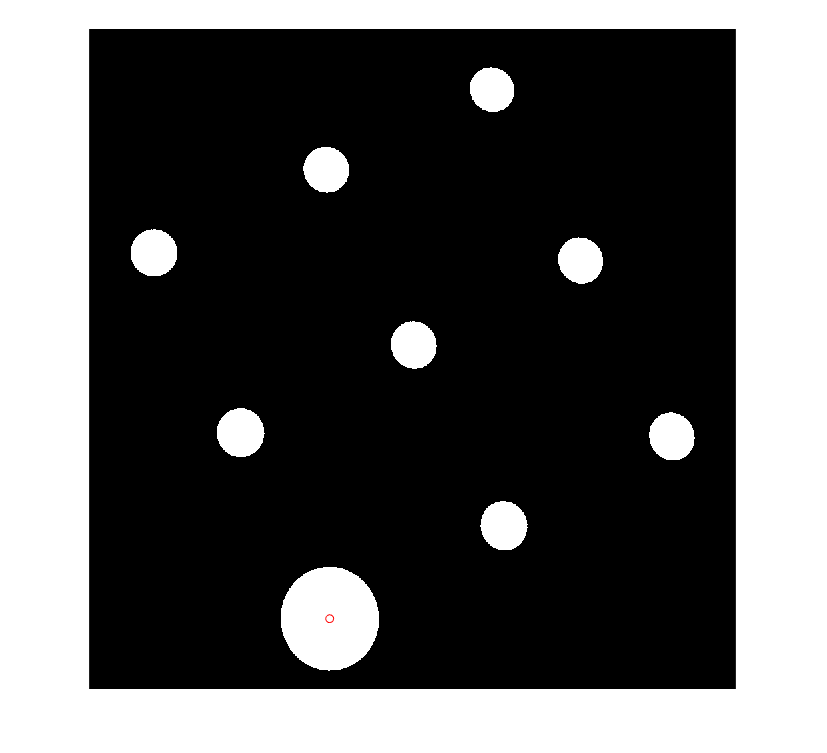

distanceSorted = sortrows( distanceFromLargest, 3);
sorted3 = sortrows( distanceSorted(1:3,:), 4);
sorted5 = sortrows( distanceSorted(4:8,:), 4);

P = [centroids(i,1:2)' sorted3(1:2,:) sorted5(1:2,:) ];
Q = [ 0 0 250 250 0 250 500 500 500; 0 250 250 0 500 500 500 250 0 ];
% ; 0 0 0 0 0 0 0 0 0 ; ones(1,9)
H = simple_homography(P,Q);





figure();
imshow(bw);
hold on;
plot(centroids(i,1), centroids(i,2), 'ro');